data_map_array=[data(:,1:5) data(:,14:15)]

data_map_array =    50.0000         0    0.1000    0.2000    0.2000    1.7879    1.0142
   50.0000         0    0.5950    0.2000    0.2000    1.8005    1.0071
   50.0000         0    1.0900    0.2000    0.2000    1.8132    1.0029
   50.0000         0    1.5850    0.2000    0.2000    1.8266    1.0006
   50.0000         0    2.0800    0.2000    0.2000    1.8407    0.9996
   50.0000         0    2.5750    0.2000    0.2000    1.8557    0.9992
   50.0000         0    3.0700    0.2000    0.2000    1.8716    0.9993
   50.0000         0    3.5650    0.2000    0.2000    1.8885    0.9995
   50.0000         0    4.0600    0.2000    0.2000    1.9064    0.9999
   50.0000         0    4.5550    0.2000    0.2000    1.9253    1.0003


**Pearson's Corelation**

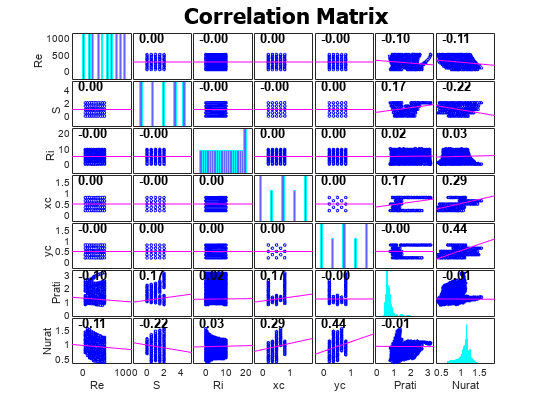

figure()
data_map_table=array2table(data_map_array, "VariableNames",{'Re','S','Ri','xc','yc','Pratio','Nuratio'});
[R,Pvalue]=corrplot(data_map_table);
data_map_array=data(:,[1 2 3 4 5 14 15]);
set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
name8=sprintf('D:/Matlab Drive/Research/Figure/Pearson/Pearson.jpg');
exportgraphics(gcf,name8)

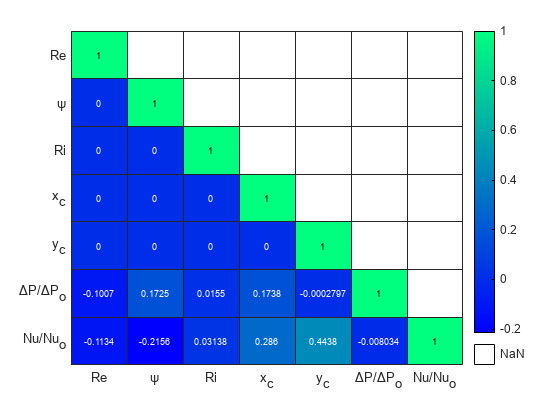

r=table2array(R);
isupper = logical(triu(ones(size(r)),1));
r(isupper) = NaN;
r(abs(r)<=0.00001)=0;
figure()
h=heatmap(r,"Colormap",winter,'MissingDataColor','w');
labels = ["Re","ψ","Ri","x_c","y_c","ΔP/ΔP_o","Nu/Nu_o"];
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
name9=sprintf('D:/Matlab Drive/Research/Figure/Pearson/heatmap.jpg');
exportgraphics(gcf,name9)

**Box Plot**

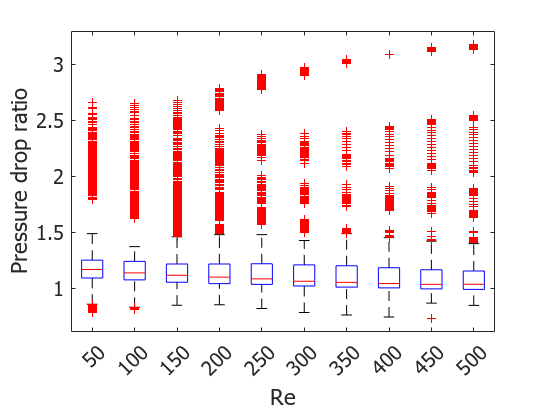

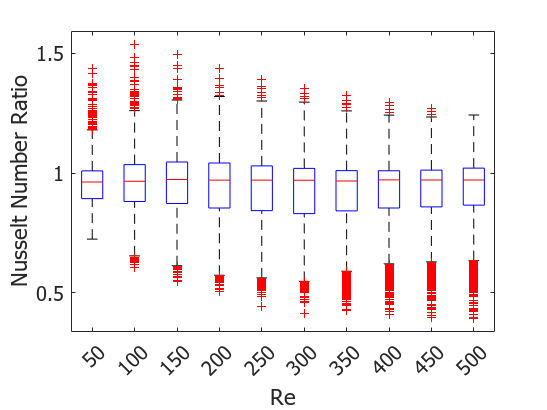

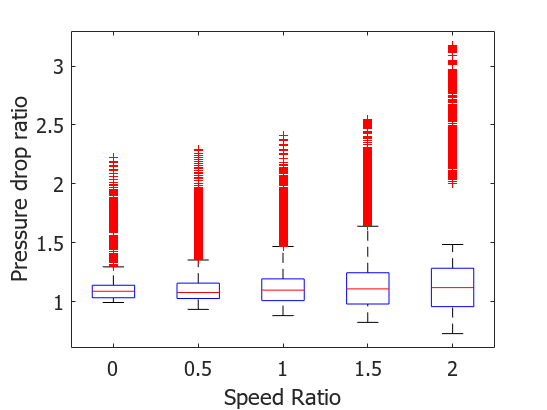

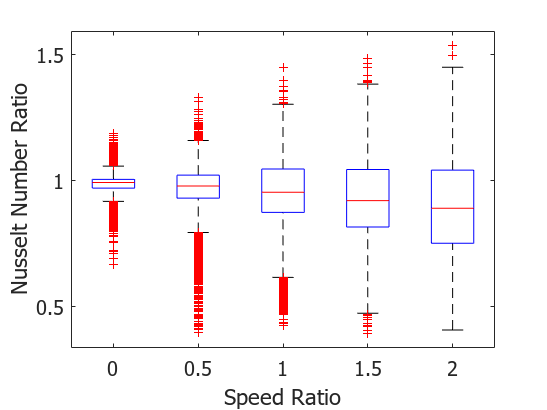

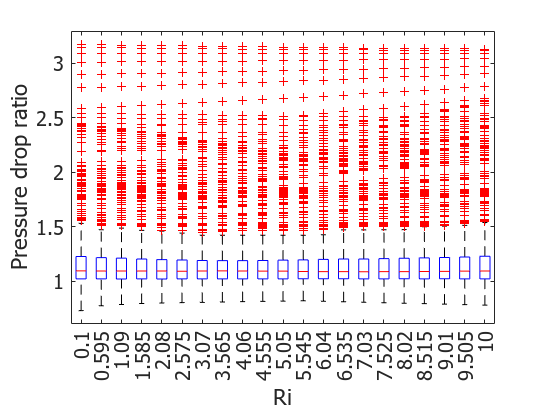

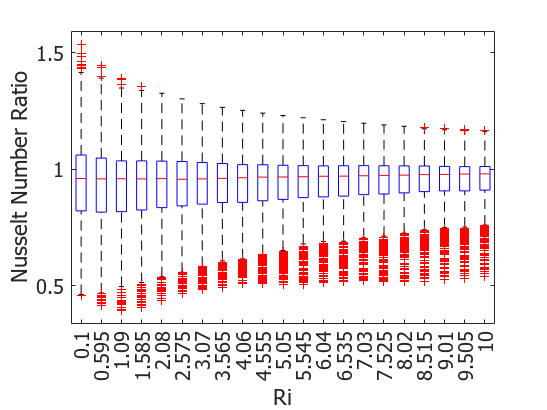

box_plot1=["Re", "Speed Ratio","Ri"];
box_plot2=["Pressure drop ratio","Nusselt Number Ratio"];
for i=1:3
    for j=6:7
        figure()
        boxplot(data_map_array(:,j),data_map_array(:,i))
        set(gca,...
        'Units','normalized',...
        'FontUnits','points',...
        'FontWeight','normal',...
        'FontSize',15,...
        'FontName','Times')
        hold on
        box_plot_name1=sprintf(box_plot1(i));
        box_plot_name2=sprintf(box_plot2(j-5));
        xlabel(box_plot_name1)
        ylabel(box_plot_name2)
        hold off
        clear xlabel
        clear ylabel
        name10=sprintf('D:/Matlab Drive/Research/Figure/Pearson/ %s vs %s boxplot.jpg',box_plot_name1,box_plot_name2);
        exportgraphics(gcf,name10)
    end
end

# **PARAM VS NU**

**Re vs Nu for different Ri x and y position**

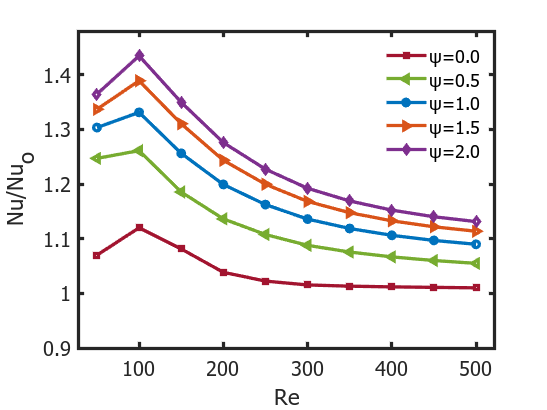

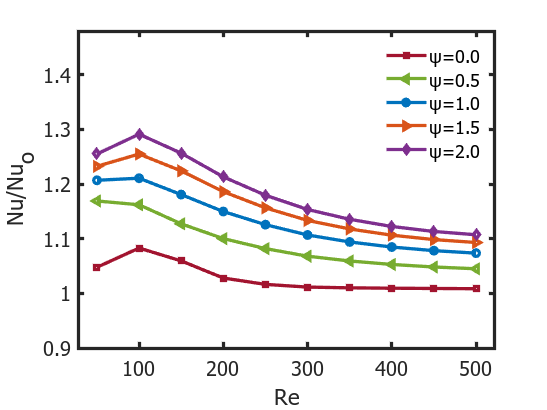

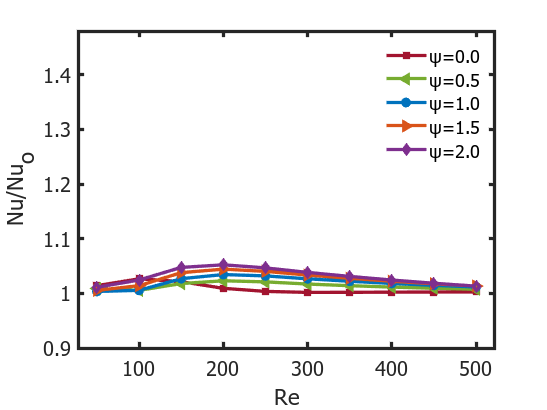

Riset=[0.1,1.09,10];
xcset=[0.5];
ycset=[0.5];
markerstring=['s','<','o','>','diamond'];
colorstring=[0.6350 0.0780 0.1840; 0.4660 0.6740 0.1880 ; 0 0.4470 0.7410 ; 0.8500 0.3250 0.0980; 0.4940 0.1840 0.5560  ];
for i=Riset
    for j=xcset
        for k=ycset
            figure();
            data2=data_map_table(data_map_table.Ri==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Re,data2.Nuratio,data2.S,colorstring,markerstring);
            set(s,'linestyle','-','LineWidth',2.5,'MarkerSize',5)
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times','LineWidth',2.5)
            xlabel('Re')
            ylabel('Nu/Nu_o')
            legend("ψ=0.0","ψ=0.5","ψ=1.0","ψ=1.5","ψ=2.0")
            ylim([0.9 1.48])
%             fig_name=sprintf('Nusselt number variation for different Reynolds numbers for different Ψ for Ri=%.3f Position xc=%.2f and yc=%.2f',i,j,k);
%             title(fig_name);
            legend('location','northeast',"Box","off");
            name1=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Re/ Nu vs Re, Ri= %.3f, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name1)
        end
    end
end

**Ri vs Nu for diff para**

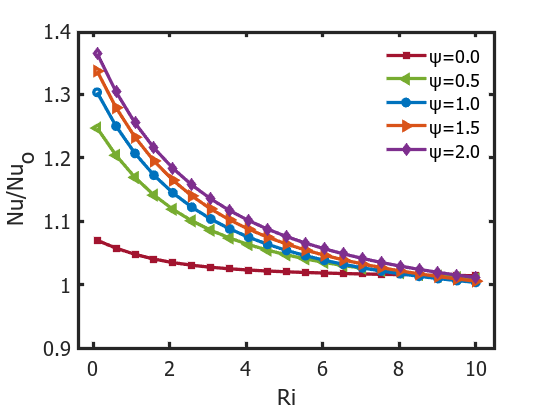

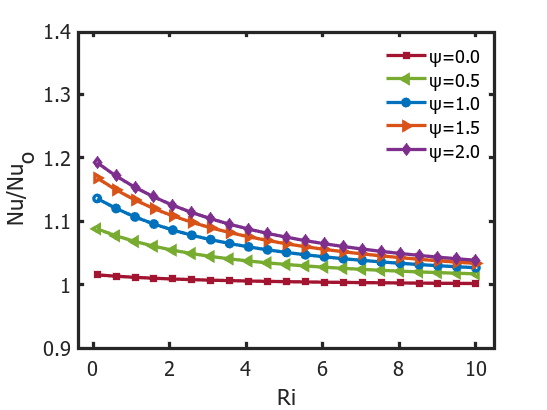

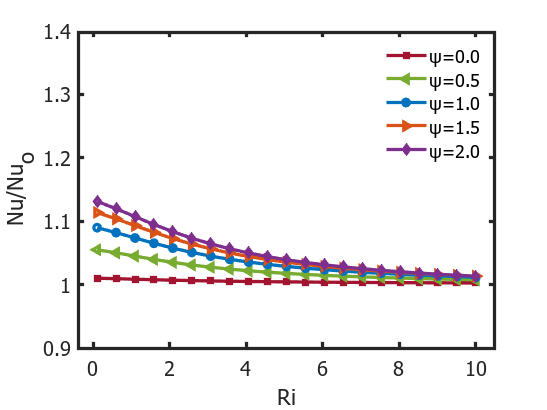

Reset=[50,300,500];
for i=Reset
    for j=xcset
        for k=ycset
            g=figure();
            data2=data_map_table(data_map_table.Re==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Ri,data2.Nuratio,data2.S,colorstring,markerstring);
            set(s,'linestyle','-','LineWidth',2.5,'MarkerSize',5)
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times','LineWidth',2.5)
            xlabel('Ri')
            ylabel('Nu/Nu_o')
            ylim([0.9 1.4])
            legend("ψ=0.0","ψ=0.5","ψ=1.0","ψ=1.5","ψ=2.0")
            
%             str=sprintf('Nusselt number variation for different Richardson numbers for different Ψ for Re=%d Position xc=%.2f and yc=%.2f',i,j,k);
%             title(str);
            legend('location','northeast',"Box","off");
            name2=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Ri/ Nu vs Ri, Re= %d, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name2)
        end
    end
end

**Nu vs Shi**

Riset=[0.1,1.09,4.06,7.03,10];
data5=[];
for i= Riset
    for j=Reset
        data4=data_map_table(data_map_table.xc==0.5 & data_map_table.yc==0.5 & data_map_table.Re==j & data_map_table.Ri==i,:);
        data5=[data5;data4];
    end
end
data5

data5 = 75×7 table
    Re      S      Ri     xc     yc     Pratio     Nuratio
    ___    ___    ____    ___    ___    _______    _______

     50      0     0.1    0.5    0.5     1.1277    1.0698 
     50    0.5     0.1    0.5    0.5     1.1348     1.247 
     50      1     0.1    0.5    0.5     1.1399    1.3033 
     50    1.5     0.1    0.5    0.5     1.1475    1.3367 
     50      2     0.1    0.5    0.5     1.1611    1.3645 
    300      0     0.1    0.5    0.5     1.0378    1.0154 
    300    0.5     0.1    0.5    0.5     1.0343    1.0878 
    300      1     0.1    0.5    0.5     1.0545    1.1359 
    300    1.5     0.1    0.5    0.5     1.0802    1.1682 
    300      2     0.1    0.5    0.5     1.1107    1.1922 
    500      0     0.1    0.5    0

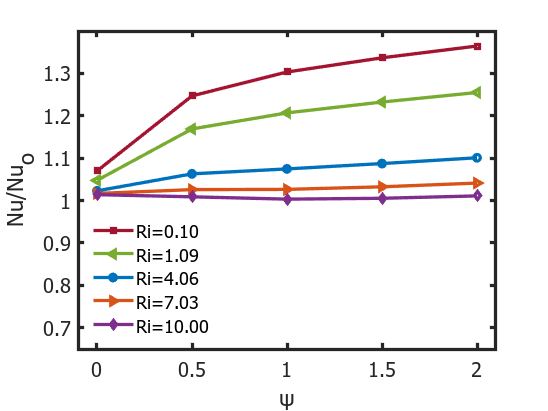

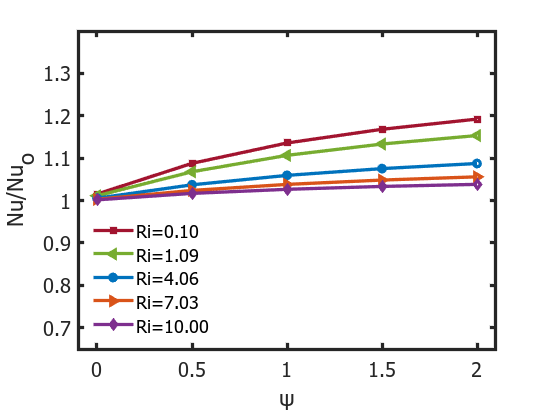

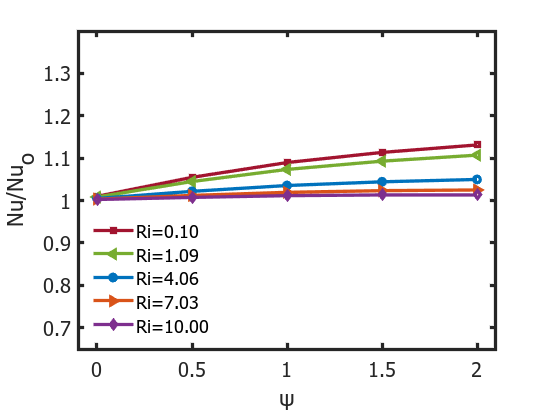

for i=Reset
    figure()
    data3=data5(data5.Re==i,:);
    s=gscatter(data3.S,data3.Nuratio,data3.Ri,colorstring,markerstring);
    set(s,'linestyle','-','LineWidth',2.5,'MarkerSize',5)
    set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times','LineWidth',2.5)
    ylim([0.65 1.4])
    xlabel("ψ")
    ylabel('Nu/Nu_o')
    legend("Ri=0.10","Ri=1.09","Ri=4.06","Ri=7.03","Ri=10.00",'Box','off','location','southwest')
    name3=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Shi/ Nu vs Shi, Re= %i.jpg',i);
    exportgraphics(gcf,name3)
end

# **PARAM VS P**

**Re vs Nu for different Ri x and y position**

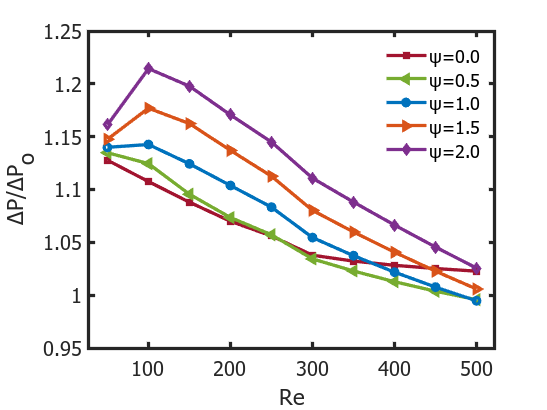

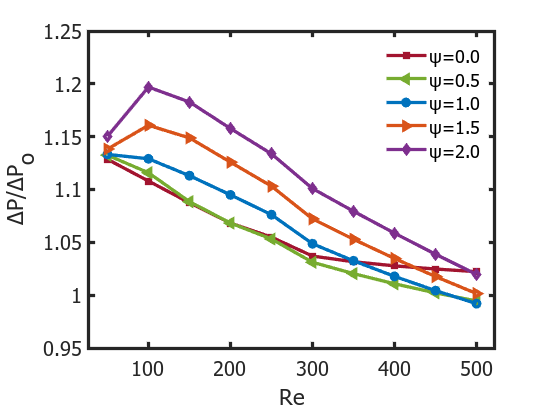

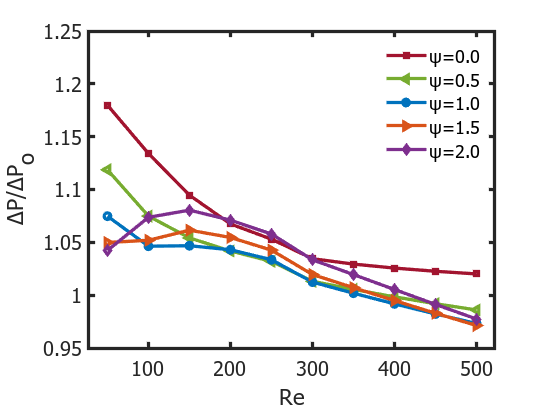

Riset=[0.1,1.09,10];
xcset=[0.5];
ycset=[0.5];
for i=Riset
    for j=xcset
        for k=ycset
            figure();
            data2=data_map_table(data_map_table.Ri==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Re,data2.Pratio,data2.S,colorstring,markerstring);
            set(s,'linestyle','-','LineWidth',2.5,'MarkerSize',5)
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times','LineWidth',2.5)
            xlabel('Re')
            ylabel('ΔP/ΔP_o')
            ylim([0.95 1.25])
            legend("ψ=0.0","ψ=0.5","ψ=1.0","ψ=1.5","ψ=2.0")
%             fig_name=sprintf('Nusselt number variation for different Reynolds numbers for different Ψ for Ri=%.3f Position xc=%.2f and yc=%.2f',i,j,k);
%             title(fig_name);
            legend('location','northeast',"Box","off");
            name4=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Re/ P vs Re, Ri= %.3f, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name4)
        end
    end
end

**Ri vs Nu for diff para**

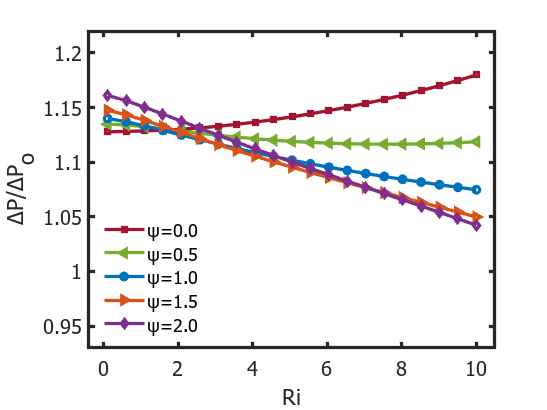

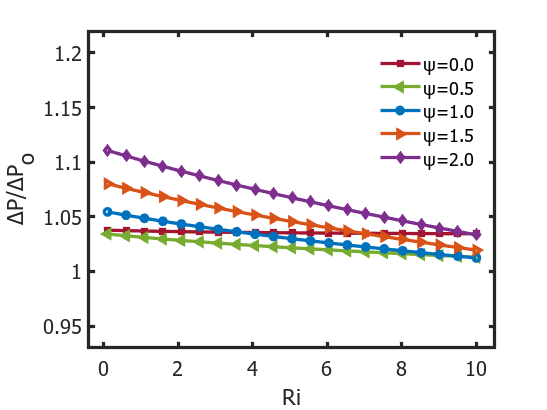

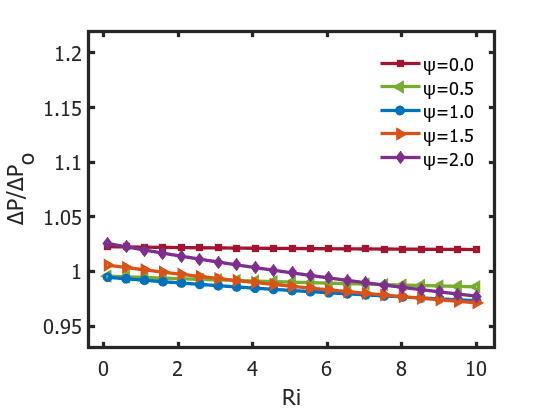

Reset=[50,300,500];
for i=Reset
    for j=xcset
        for k=ycset
            g=figure();
            data2=data_map_table(data_map_table.Re==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Ri,data2.Pratio,data2.S,colorstring,markerstring);
            set(s,'linestyle','-','LineWidth',2.5,'MarkerSize',5)
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times','LineWidth',2.5)
            xlabel('Ri')
            ylabel('ΔP/ΔP_o')
            ylim([0.93 1.22])
            legend("ψ=0.0","ψ=0.5","ψ=1.0","ψ=1.5","ψ=2.0",'Box','off')
%             str=sprintf('Nusselt number variation for different Richardson numbers for different Ψ for Re=%d Position xc=%.2f and yc=%.2f',i,j,k);
%             title(str);
            if i==50 
                legend('location','southwest',"Box","off");
            end
%             elseif i==300
%                 legend('location','northeast',"Box","off");
%             else
%                 legend('position',[0.62 0.5 0.3 0.2],"Box","off")
%             end
            name5=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Ri/ P vs Ri, Re= %d, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name5)
        end
    end
end

**Nu vs Shi**

Riset=[0.1,1.09,4.06,7.03,10];
data5=[];
for i= Riset
    for j=Reset
        data4=data_map_table(data_map_table.xc==0.5 & data_map_table.yc==0.5 & data_map_table.Re==j & data_map_table.Ri==i,:);
        data5=[data5;data4];
    end
end
data5

data5 = 75×7 table
    Re      S      Ri     xc     yc     Pratio     Nuratio
    ___    ___    ____    ___    ___    _______    _______

     50      0     0.1    0.5    0.5     1.1277    1.0698 
     50    0.5     0.1    0.5    0.5     1.1348     1.247 
     50      1     0.1    0.5    0.5     1.1399    1.3033 
     50    1.5     0.1    0.5    0.5     1.1475    1.3367 
     50      2     0.1    0.5    0.5     1.1611    1.3645 
    300      0     0.1    0.5    0.5     1.0378    1.0154 
    300    0.5     0.1    0.5    0.5     1.0343    1.0878 
    300      1     0.1    0.5    0.5     1.0545    1.1359 
    300    1.5     0.1    0.5    0.5     1.0802    1.1682 
    300      2     0.1    0.5    0.5     1.1107    1.1922 
    500      0     0.1    0.5    0

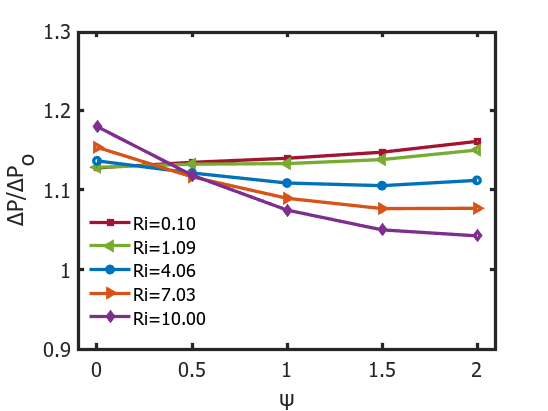

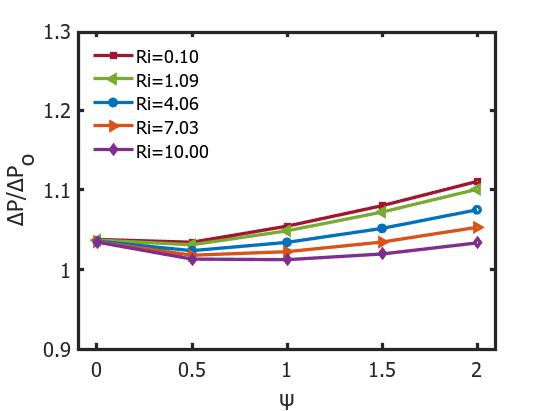

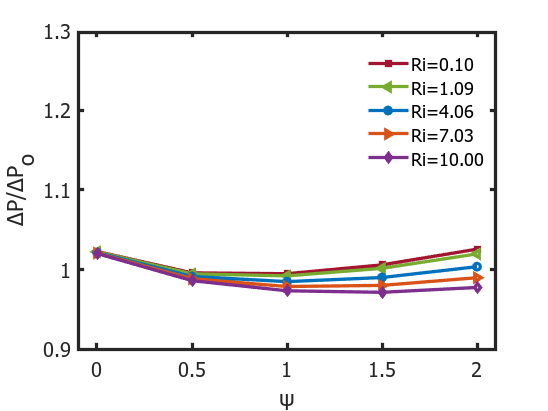

for i=Reset
    figure()
    data3=data5(data5.Re==i,:);
    s=gscatter(data3.S,data3.Pratio,data3.Ri,colorstring,markerstring);
    set(s,'linestyle','-','LineWidth',2.5,'MarkerSize',5)
    set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times','LineWidth',2.5)
    xlabel("ψ")
    ylabel("ΔP/ΔP_o")
    ylim([0.9 1.3])
    if i==300
        legend('location','northwest')
    end
    legend("Ri=0.10","Ri=1.09","Ri=4.06","Ri=7.03","Ri=10.00",'Box','off')
    name6=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Shi/ P vs Shi, Re= %i.jpg',i);
    exportgraphics(gcf,name6)
end

# **Surface Plot**

**Position Vs Nu**

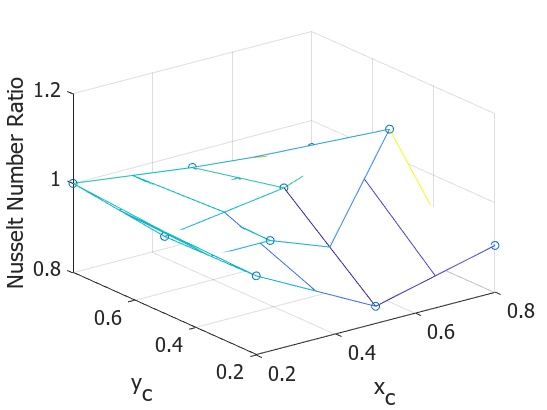

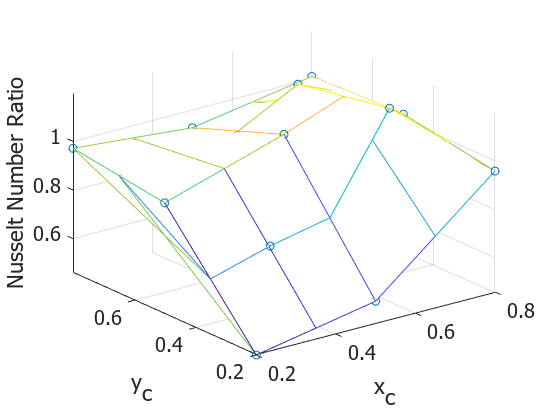

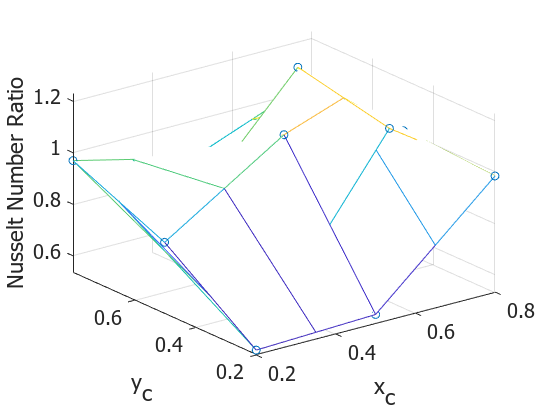

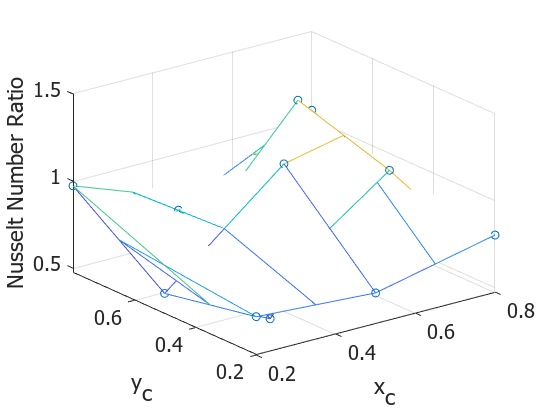

Sset=[0 0.5 1 2];
Reset_surf=[300];
Riset_surf=[1.09];
for i = Reset_surf
    for j= Riset_surf
        for k=Sset
            figure()
            data7=data_map_table(data_map_table.Re==i & data_map_table.Ri==j & data_map_table.S==k,:);
            [xq,yq] = meshgrid(data7.xc,data7.yc);
            vq = griddata(data7.xc,data7.yc,data7.Nuratio,xq,yq);  %(x,y,v) being your original data for plotting points
            mesh(xq,yq,vq)
            hold on
            plot3(data7.xc,data7.yc,data7.Nuratio,'o')
            set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
            xlabel("x_c")
            ylabel("y_c")
            zlabel("Nusselt Number Ratio")
            name7=sprintf('D:/Matlab Drive/Research/Figure/Position vs Nu/ Re=%0.3f, Ri=%0.3f, shi=%0.3f surfaceplot(Nusselt).jpg',i,j,k);
            exportgraphics(gcf,name7)
        end
    end
end

**Position Vs P**

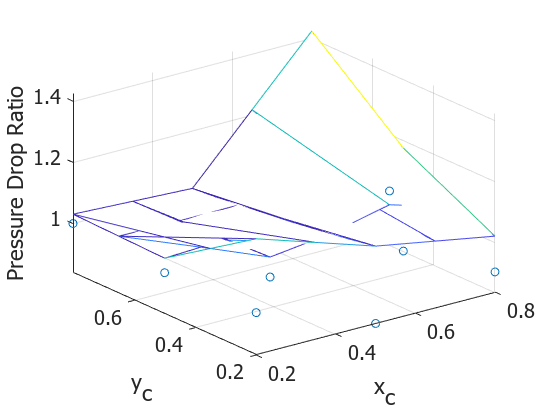

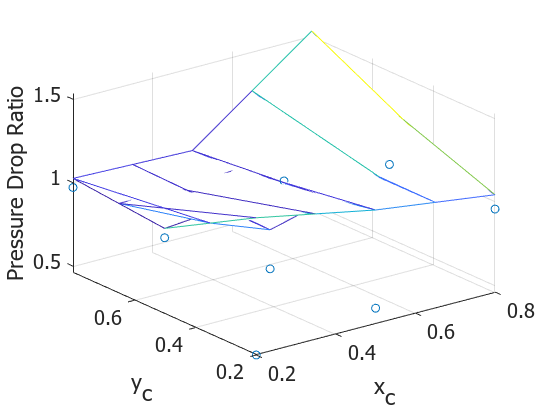

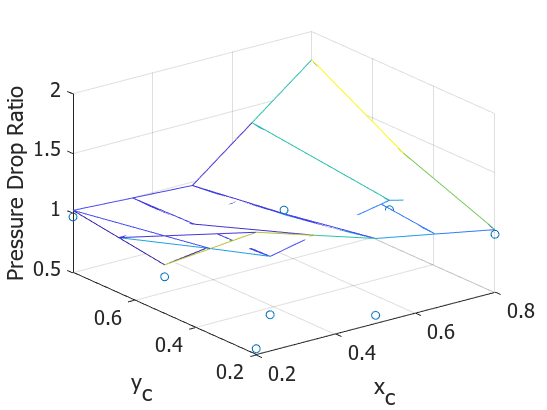

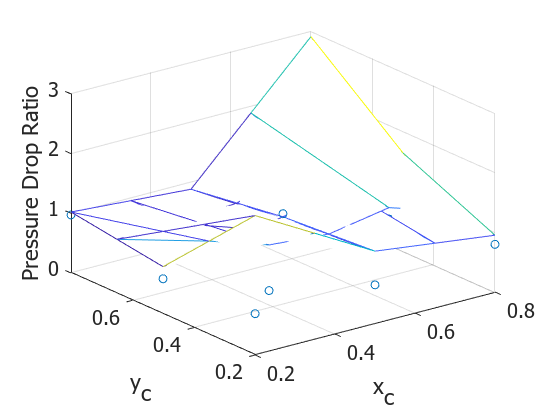

for i = Reset_surf
    for j= Riset_surf
        for k=Sset
            figure()
            data7=data_map_table(data_map_table.Re==i & data_map_table.Ri==j & data_map_table.S==k,:);
            [xq,yq] = meshgrid(data7.xc,data7.yc);
            vq = griddata(data7.xc,data7.yc,data7.Pratio,xq,yq);  %(x,y,v) being your original data for plotting points
            mesh(xq,yq,vq)
            hold on
            plot3(data7.xc,data7.yc,data7.Nuratio,'o')
            set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
            xlabel("x_c")
            ylabel("y_c")
            zlabel("Pressure Drop Ratio")
            name7=sprintf('D:/Matlab Drive/Research/Figure/Position vs Nu/ Re=%0.3f, Ri=%0.3f, shi=%0.3f surfaceplot(Pressure).jpg',i,j,k);
            exportgraphics(gcf,name7)
        end
    end
end